Loading In Rosbag

bagSelect = rosbag('2022-07-21-23-00-37.bag');

Parse Data Topics

% Voltage Parsing 
voltageLog = select(bagSelect, 'Topic', '/amr/status/voltage');
voltagePlot = readMessages(voltageLog)

voltagePlot = 35×1 cell array
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}


[voltageLength,~] = size(voltagePlot) 

voltageLength = 35

voltage = zeros(voltageLength,1)

voltage =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i = 1:voltageLength
    voltage(i,1) = voltagePlot{i}.Data;
end

% Current Parsing 
currentLog = select(bagSelect, 'Topic', '/amr/status/current');
currentPlot = readMessages(currentLog)

currentPlot = 34×1 cell array
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}
    {1×1 Float32}


[currentLength,~] = size(currentPlot) 

currentLength = 34

current = zeros(currentLength,1)

current =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i = 1:currentLength
    current(i,1) = abs(currentPlot{i}.Data);
end

% Encoder Parsing 
encoderLog = select(bagSelect, 'Topic','/zlac8015d/encoder');
encoderPlot = readMessages(encoderLog);
[encoderLength,~] = size(encoderPlot);
leftEncoder = zeros(encoderLength,1);
rightEncoder = zeros(encoderLength,1);
for i = 1:encoderLength
    leftEncoder(i,1) = encoderPlot{i}.Data(1,:);
    rightEncoder(i,1) = encoderPlot{i}.Data(2,:);
end

% Encoding Parsing
rpmLog = select(bagSelect, 'Topic', '/zlac8015d/measured_RPM');
rpmPlot = readMessages(rpmLog);
[rpmLength,~] = size(rpmPlot);
leftRPM = zeros(rpmLength,1);
rightRPM = zeros(rpmLength,1);
for i = 1:rpmLength
    leftRPM(i,1) = rpmPlot{i}.Data(1,:);
    rightRPM(i,1) = rpmPlot{i}.Data(2,:);
end

Plot Voltage Data

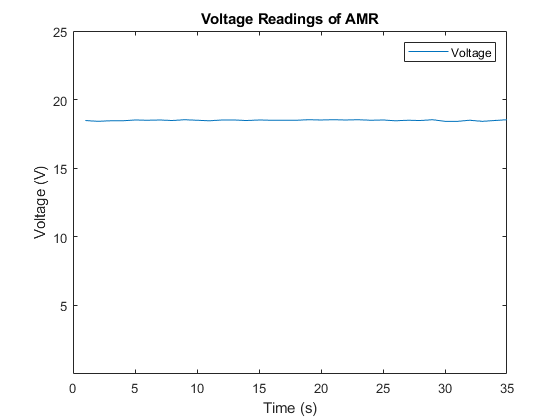

plot(voltage);
title('Voltage Readings of AMR');
xlabel('Time (s)');
ylabel('Voltage (V)');
legend('Voltage')
ylim([0 25]);

Plot Current Data

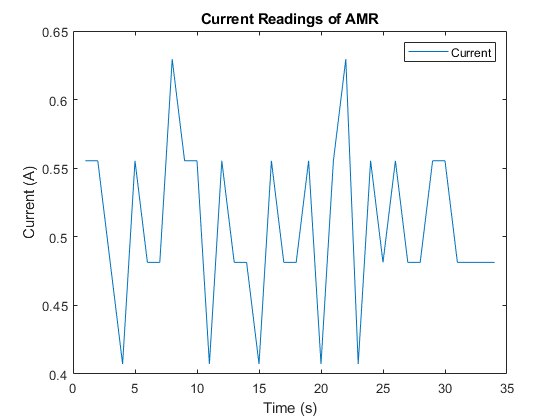

plot(current);
title('Current Readings of AMR');
xlabel('Time (s)');
ylabel('Current (A)');
legend('Current')

Plot Wheel Encoder Data

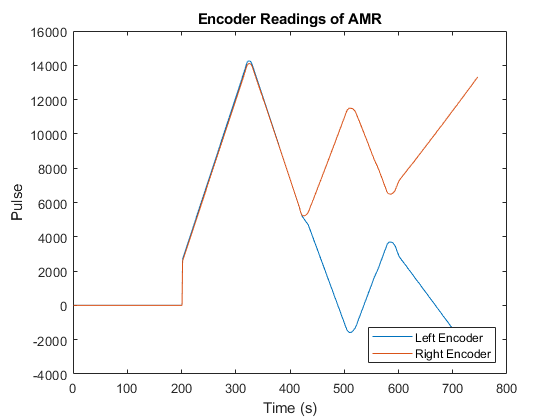

plot(leftEncoder);
hold on
title('Encoder Readings of AMR');
xlabel('Time (s)');
ylabel('Pulse');    
plot(rightEncoder);
legend('Left Encoder', 'Right Encoder', 'Location', 'southeast')
hold off 

Plot Measured RPM Data 

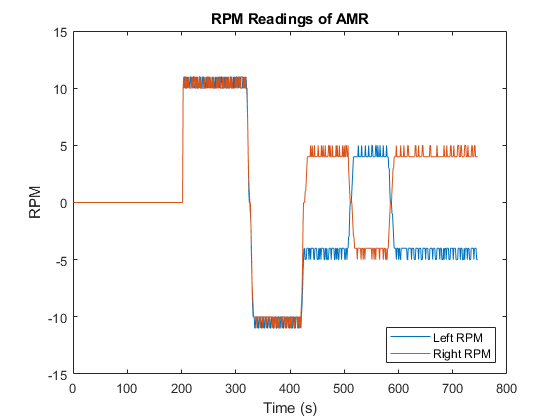

plot(leftRPM);
hold on
title('RPM Readings of AMR');
xlabel('Time (s)');
ylabel('RPM');
plot(rightRPM);
legend('Left RPM', 'Right RPM', 'Location', 'southeast')
hold off

% title('Right RPM Readings of AMR');
% xlabel('Time (s)');
% ylabel('RPM');

Plot Calculated RPM Data 